% Dataset

Error using load
Unable to read file 'main.mlx'. Input must be a MAT-file or an ASCII file containing numeric data with same number of columns in each row.

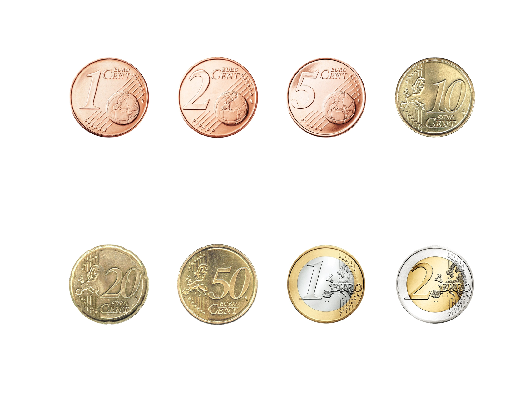

xTrainImages{1} = imread('Münzen\1ct.jpg');
xTrainImages{2} = imread('Münzen\2ct.jpg');
xTrainImages{3} = imread('Münzen\5ct.jpg');
xTrainImages{4} = imread('Münzen\10ct.jpg');
xTrainImages{5} = imread('Münzen\20ct.jpg');
xTrainImages{6} = imread('Münzen\50ct.jpg');
xTrainImages{7} = imread('Münzen\1e.jpg');
xTrainImages{8} = imread('Münzen\2e.jpg');

tTrain = eye(8);

%[xTrainImages, tTrain] = digitTrainCellArrayData; % In unserem Fall: Geladene Trainingsdaten
for i=1:8
    xTrainImages{i} = imresize(xTrainImages{i}, [256 256]);
    subplot(2,4,i);
    imshow(xTrainImages{i});
end

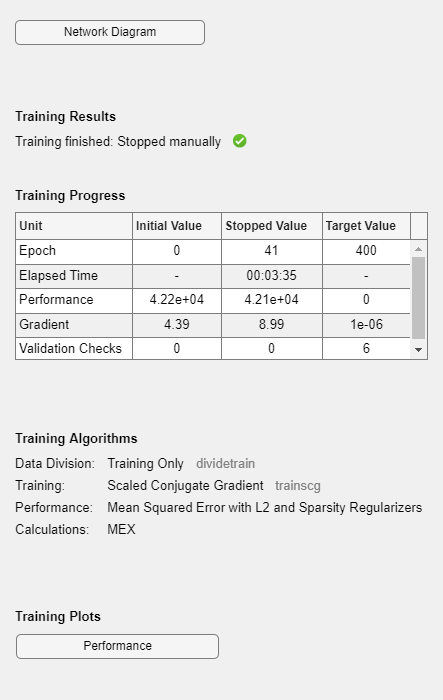

% Train first Autoencoder
rng('default');
hiddenSize1 = 100;

autoenc1 = trainAutoencoder(xTrainImages, hiddenSize1, ...
    'MaxEpochs', 400, ...
    'L2WeightRegularization', 0.04, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.15, ...
    'ScaleData', false);

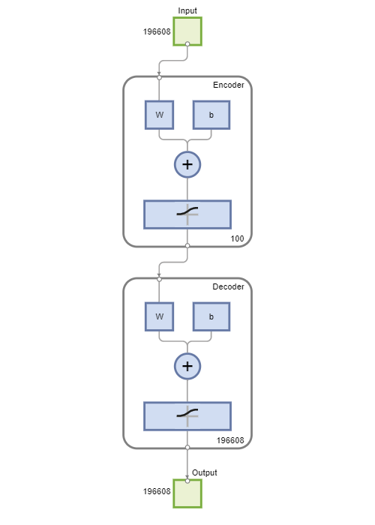


view(autoenc1)

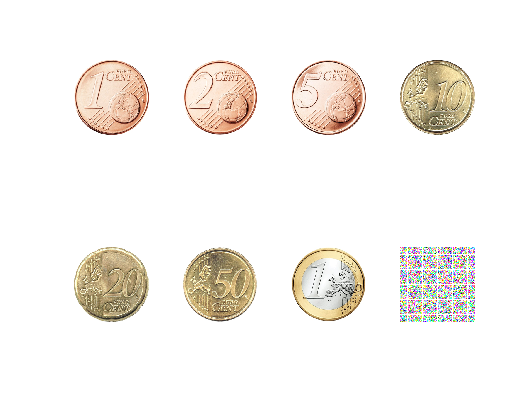

% Plot
plotWeights(autoenc1);


feat1 = encode(autoenc1, xTrainImages);

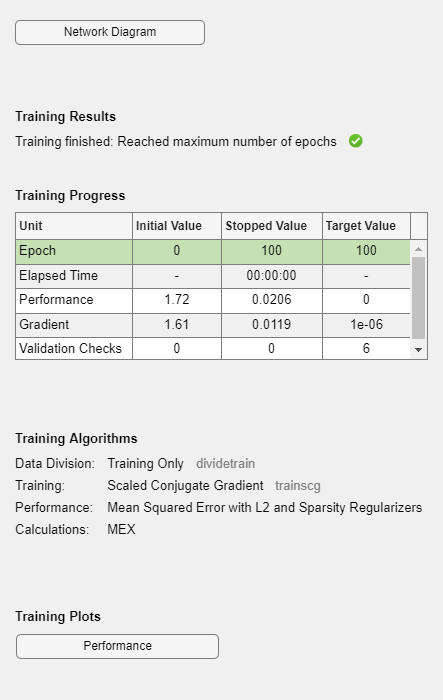

% Trainieren vom 2. Autoencoder
hiddenSize2 = 50;
autoenc2 = trainAutoencoder(feat1, hiddenSize2, ...
    'MaxEpochs', 100, ...
    'L2WeightRegularization', 0.002, ...
    'SparsityRegularization', 4, ...
    'SparsityProportion', 0.1, ...
    'ScaleData', false);

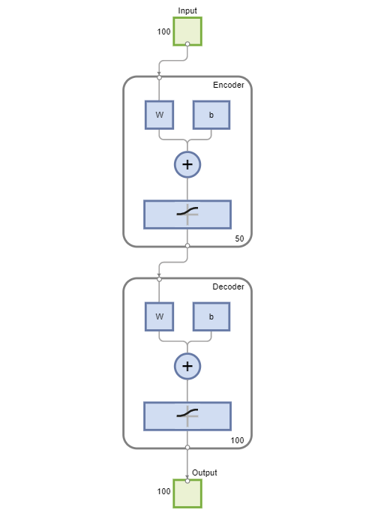


view(autoenc2)


feat2 = encode(autoenc2,feat1);

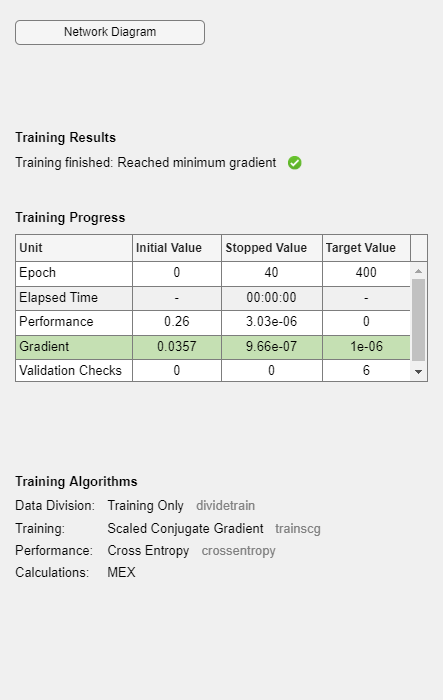

% Softmax-Layer trainieren
softnet = trainSoftmaxLayer(feat2, tTrain, 'MaxEpochs', 400);

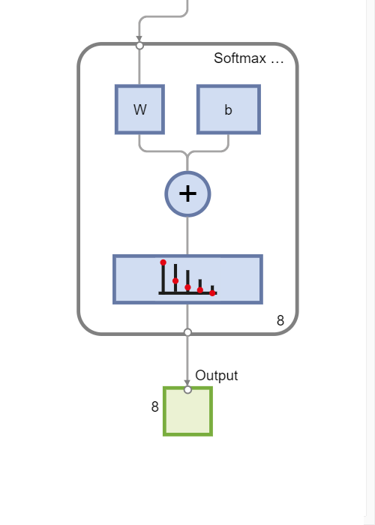

view(softnet)

% StackedNet
stackednet = stack(autoenc1, autoenc2, softnet);

% Bildgröße
imWidth = 256;
imHeight = 256;
inputSize = imWidth * imHeight * 3;

% Laden der Testbilder
%[xTestImages,tTest] = digitTestCellArrayData;

%xTestImages = cell()

for i=1:16
    xTestImages{i} = imresize(imread(sprintf("readCoins/img_%02d.jpg",i)), [256 256]);
end

tTest = [1 1 1 0 0 0 3 2]';

% Testbilder in Vektoren und die Rüstung
xTest = zeros(inputSize, 1);
%for i = 1:numel(xTestImages)
    xTest(:,1) = xTestImages{1}(:);
%end

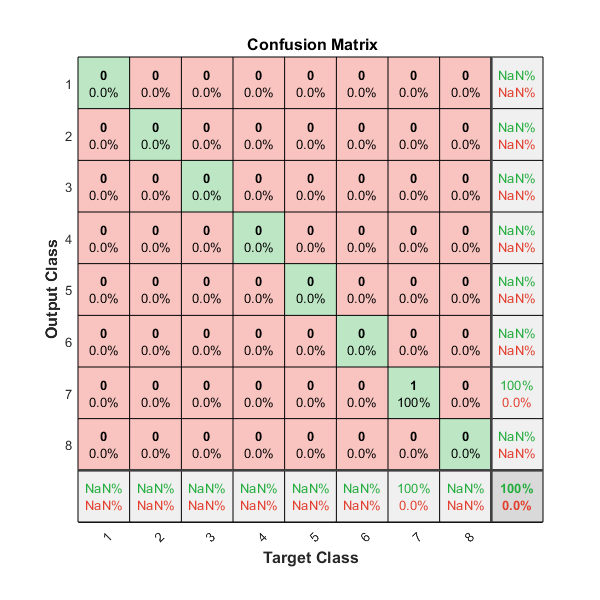

% Visualisieren
y = stackednet(xTest);
plotconfusion(tTest,y);

% In Vektor umwandeln
xTrain = zeros(inputSize, numel(xTrainImages));
for i=1:numel(xTrainImages)
    xTrain(:, i) = xTrainImages{i}(:);
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.


stackednet = train(stackednet, xTrain, tTrain);
y = stackednet(xTest);
plotconfusion(tTest,y);